# Etapa 2.  Gráfica de líneas de campo magnético (2D) para un dipolo magnético.

## Datos iniciales

%Constantes
NumPuntos = 75; %Numero de cargas a graficar a través del aro
radio = 45; %Radio aro
miu = 4*pi*10^-7; %Constante de permeabildiad
I = 200; %Corriente

## Espacio

spacex = linspace(-75,75,NumPuntos); %Vector de espacio en X
spacey = linspace(-75,75,NumPuntos); %Vector de espacio en Y
[X,Y] = meshgrid(spacex,spacey); %Matriz de espacio

## Cálculo del campo

NumEspiras = 10;    %Espiras totales que tendrá el solenoide
separacion = 5;     %Separación entre las espiras
posinicial = 0;     %Variable auxiliar
totx = zeros(size(X));
toty = zeros(size(Y));
%Ciclo for para graficar cada campo
for i=1:NumEspiras;
    %Vector de puntos
    r = sqrt((X+separacion).^2 + (Y+separacion).^2);
    % Campos por componente
    %Ecuaciones para X
    CampoX1 = (miu*I*(pi*radio)^2);
    CampoX2 = 3.*X.*Y;
    CampoX3 = 4.*(r.^3);
    CampoX4 = r.^2;
    % Ecucaciones para Y
    CampoY1 = (miu*I*(pi*radio)^2);
    CampoY2 = 3.*(Y.^2);
    CampoY3 = 4.*(r.^3);
    CampoY4 = r.^2;
    %Campos totales
    CampoX = (CampoX1./CampoX3).*(CampoX2./CampoX4);
    CampoY = ((CampoY1./CampoY3).*((CampoY2./CampoY4)-1));
    CampoTotal = sqrt(CampoX.^2 + CampoY.^2);
    CampX = CampoX./CampoTotal;
    CampY= CampoY./CampoTotal;
    posinicial = posinicial + separacion;   %Aumentando el valor de la variable inicial
    totx = totx + CampX;
    toty = toty + CampY;
end


## Graficando

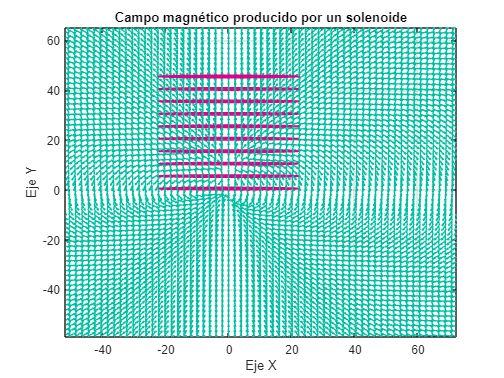

quiver(X,Y,totx,toty,Color="#00C0A3");   %Graficando el campo e iterando para tener un campo resultante de todas las espiras
axis([-75 75 -75 75]);  %Eje
grid on;     %Grid
hold on;
NumEspiras = 10;    %Espiras totales que tendrá el solenoide
separacion = 5;     %Separación entre las espiras
posinicial = 0;     %Variable auxiliar
for i=1:NumEspiras;
    quiver(X,Y,CampX,CampY + separacion,Color="#00C0A3");   %Graficando el campo e iterando para tener un campo resultante de todas las espiras
    axis([-75 75 -75 75]);  %Eje
    grid on;     %Grid
    hold on;
    rectangle('Position',[-radio/2 posinicial radio 1],'Curvature',[1 1],'Facecolor',"#e60088",'Edgecolor',"#e60088");     %Graficando cada anillo
    hold on;
    posinicial = posinicial + separacion;   %Aumentando el valor de la variable inicial
end
hold off;
xlabel('Eje X');
ylabel('Eje Y');
title("Campo magnético producido por un solenoide")